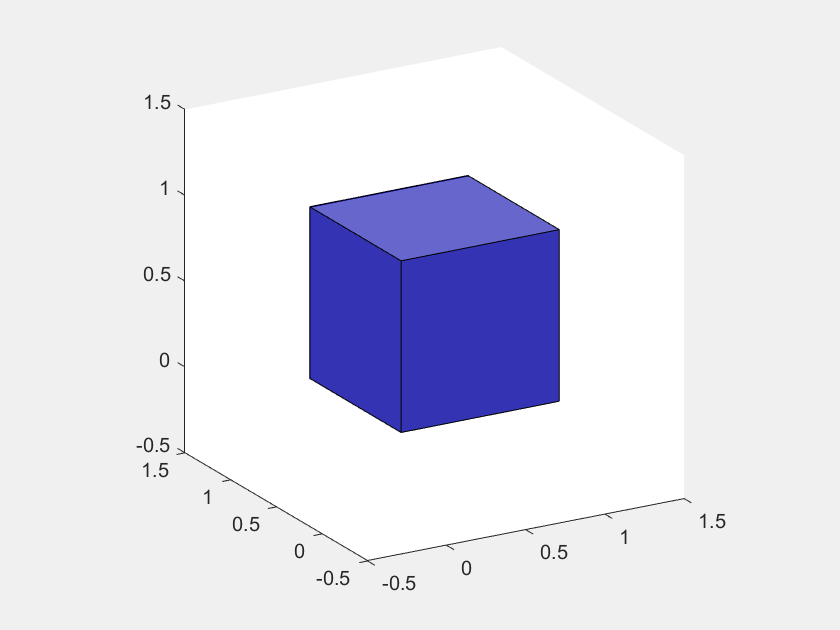

close all 
clear

f = figure("Visible","on");
disableDefaultInteractivity(gca)
set(gca,"Clipping","off")
quivColor = [0.7,0.3,0.1];
c = [0 0 0.5; 0.4 0.4 0.8; 0.2 0.2 0.7; 0 0 0.5; 0.2 0.2 0.7; 0 0 0.5];
[vertices,faces,normals] = cubeValues();
for k = 1:6
    patch("Vertices",vertices,"Faces",faces(k,:),...
          "FaceColor","Flat","FaceVertexCData",c(k,:),"FaceAlpha",1,...
          "ButtonDownFcn",{@createQuiver,normals(k,:)/2,quivColor});
end

axis equal
view(-30,20)
axis([-1,1,-1,1,-1,1]*1 + 0.5)

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

function createQuiver(src,evt,n,color) 
    p = evt.IntersectionPoint;
    scale = 0;
    hold on
    plot3(p(1),p(2),p(3),".","Color",color)
    quiverObj = quiver3(p(1),p(2),p(3),scale*n(1),scale*n(2),scale*n(3),"linewidth",1,...
        "Autoscale","off","MaxHeadSize",0.3,"Color",color);
    hold off
    axp = src.Parent; % Get the handle to the parent axes
    figp = axp.Parent; % Get the handle to the parent figure

    % Button up callback: stop editing
    dim = find(n~=0);
    figp.WindowButtonUpFcn = @releaseQuiver;
    figp.WindowButtonMotionFcn = {@resizeQuiver,quiverObj,p,dim,n};
end

function resizeQuiver(src,evt,quiverObj,p,dim,n)

    % Compute where the point intersects with the
    % perpendicular plane
    cp = get(gca,"CurrentPoint");

    % Compute the plane through which the arrow will move
    v = cp(1,:) - cp(2,:);
    u = cross(v,n);
    m = cross(u,n); % Plane normal

    % Identify where the ray went through the plane
    s = planeIntersection(cp(1,:),cp(2,:),m,p);  

    % Scale the arrow based on the intersecting point
    deltap = s-p;
    scale = deltap(dim);
    if(dim == 1)
        quiverObj.UData = scale;
    elseif(dim == 2)
        quiverObj.VData = scale;
    else
        quiverObj.WData = scale;
    end
end

function releaseQuiver(src,evt) 
    % When the button has been released
    % clear the callbacks
    src.WindowButtonUpFcn = {};
    src.WindowButtonMotionFcn = {};
end

function s = planeIntersection(q,r,n,p)
    % Inputs:
    %   q,r: distinct points along line [x,y,z]
    %   n: plane normal vector [nx,ny,nz]
    %   p: point in the plane [x,y,z]
    % Outputs:
    %   s: intersection point [x,y,z]
    %      (returns NaNs if line || plane)
    
    v = r-q; % line vector

    % Select equations for the matrix
    % to avoid singular cases
    if( v(3)~=0 && any([n(3),v(1),v(2)]~=0) )
        Al = [ v(3)     0 -v(1);
                  0  v(3) -v(2)];
        bl = [-v(3)*q(1) + v(1)*q(3);
              -v(3)*q(2) + v(2)*q(3)];
    elseif( v(1)~=0 && any([n(1),v(2),v(3)]~=0) )
        Al = [ v(2) -v(1)     0;
               v(3)    0  -v(1)];
        bl = [-q(1)*v(2) + v(1)*q(2);
              -q(1)*v(3) + v(1)*q(3)];
    else
        Al = [ v(2) -v(1)    0;
               v(3)    0  -v(2)];
        bl = [-q(1)*v(2) + v(1)*q(2);
              -q(2)*v(3) + v(2)*q(3)];
    end
    
        
    % Set up and solve the matrix system
    A = [Al; n];
    b = [bl; dot(n,-p)];

    if(abs(det(A))<1e-12) % Singular case
        % If the plane and line are parallel, return NaNs
        s = [NaN, NaN, NaN];
    else
        s = (A\-b)';
    end
end

%#ok<*INUSD> 